% DPS Data Analysis Script
% Sets current directory as working directory
% Defines pass/fail thresholds
% Pulls data and populates into data structure
% Evaluates force vs. displacement
% Evaluates work
% Plots the f-d and w-d graphs

%%Changelog - V3.0 - May 2024
%Removed close, clear commands from beginning
%Prompts user for 'data' folder directory
%Moved parameter definition below file path and data extraction
%Modified path list commands for error-handling
%Changed definition of upper/lower limits of displacement gates
%Added work value limits
%Added in calculation of work
%Modified data structure to include new work values and pass/fail criteria
%Updated f-d plot for readability; add export to PDF step
%Added w-d plot; export to PDF
%Updated pathlist function to match updates to path list commands
%getCSVdata function array preallocated; additional error-handling
%Created pass/fail function for clarity/readability
%Added preallocation/error-handling to writestructure function

% Prompt user to select the folder containing the 'data' folder
%ex: M:\Production Performance Testing\Test Data Processing\1011457\MOXXXXX\MOXXXXX FAT DAY-2
parentFolder = uigetdir(pwd, 'Select folder containing "data" ');

% Check if the user canceled the folder selection
if parentFolder == 0
    disp('Folder selection canceled. Exiting script.');
    return;
end

% Generate path list
mainsearchpath = fullfile(parentFolder, 'data');
filesearchstrings = {'*.dat', '*.DAT', '*.Dat'};
pathlist = generatePathList(mainsearchpath, filesearchstrings);

% Display pathlist
disp('Path List:');

Path List:


disp(pathlist);

    {'M:\Production Performance Testing\Test Data Processing\1011457\MO32246\MO32246 FAT DAY-2\data\PN1011457_MO32246_DAY-2_168-1_001.Dat'}
    {'M:\Production Performance Testing\Test Data Processing\1011457\MO32246\MO32246 FAT DAY-2\data\PN1011457_MO32246_DAY-2_170-2_001.Dat'}
    {'M:\Production Performance Testing\Test Data Processing\1011457\MO32246\MO32246 FAT DAY-2\data\PN1011457_MO32246_DAY-2_171-1_001.Dat'}
    {'M:\Production Performance Testing\Test Data Processing\1011457\MO32246\MO32246 FAT DAY-2\data\PN1011457_MO32246_DAY-2_176-2_001.Dat'}
    {'M:\Production Performance Testing\Test Data Processing\1011457\MO32246\MO32246 FAT DAY-2\data\PN1011457_MO32246_DAY-2_180-2_001.Dat'}
    {'M:\Production Performance Testing\Test Data Processing\1011457\MO32246\MO32246 FAT DAY-2\data\PN1011457_MO32246_DAY-2_181-1_001.Dat'}
    {'M:\Production Performance Testing\Test Data Processing\1011457\MO32246\MO32246 FAT DAY-2\data\PN1011457_MO32246_DAY-2_185-1_001.Dat'}
    {'M:\Production 

% Define parameters, pass/fail metrics
fz = 2; % Set zeroing value, lbf

% Define Force Gates for each displacement
val0p2USL = 325; % Upper limit returned force @ 0.2" displacement, lbf
val0p2LSL = 135; % Lower limit returned force @ 0.2" displacement, lbf
val0p7USL = 480; % Upper limit returned force @ 0.7" displacement, lbf
val0p7LSL = 240; % Lower limit returned force @ 0.7" displacement, lbf

% Define Work Value Limits at 0.7" displacement
work_Ul = 230; % Upper work limit, in-lbf
work_Ll = 100; % Lower Work Limit, in-lbf

%Initialize counters
totalFiles = 0;
failCount0p2 = 0;
failCount0p7 = 0;
failCountWork = 0;

% Extract data from .DAT files and put into data structure
skiplines = 4; % Ignore first four lines of data
columnnames = {'force', 'disp', 'time'}; % Names of columns to be extracted
columnindexes = [1, 2, 4]; % Column index corresponding to 'columnnames'
data = getCSVdata(pathlist, skiplines, columnnames, columnindexes);

for i = 1:length(data)
    totalFiles = totalFiles + 1; % Increment total files counter

    % Zero force displacement
    fstop1 = find(data(i).force > fz, 1);
    fstart1 = fstop1 - 1;
    data(i).fz = interp1(data(i).force(fstart1:fstop1), data(i).disp(fstart1:fstop1), fz);

    % Evaluate force-displacement at specific points
    try
        data(i).val0p2 = interp1(data(i).disp - data(i).fz, data(i).force, 0.2);
        data(i).val0p7 = interp1(data(i).disp - data(i).fz, data(i).force, 0.7);
    catch
        % Add small noise to avoid interpolation errors
        noise1 = rand(length(data(i).force), 1) * 0.000001;
        noise2 = rand(length(data(i).disp), 1) * 0.000001;
        data(i).val0p2 = interp1(data(i).disp - data(i).fz + noise2, data(i).force + noise1, 0.2);
        data(i).val0p7 = interp1(data(i).disp - data(i).fz + noise2, data(i).force + noise1, 0.7);
    end

    % Determine pass/fail for force at specific displacements
    data(i).val0p2Result = determinePassFail(data(i).val0p2, val0p2LSL, val0p2USL);
    if ~strcmp(data(i).val0p2Result, 'Pass')
        failCount0p2 = failCount0p2 + 1; % Increment fail counter for 0.2" displacement
    end

    data(i).val0p7Result = determinePassFail(data(i).val0p7, val0p7LSL, val0p7USL);
    if ~strcmp(data(i).val0p7Result, 'Pass')
        failCount0p7 = failCount0p7 + 1; % Increment fail counter for 0.7" displacement
    end

    % Calculate work done at 0.7" displacement using trapezoidal rule
    idx0p7 = find(data(i).disp - data(i).fz <= 0.7, 1, 'last');
    if isempty(idx0p7)
        data(i).work = NaN; % In case there is no data up to 0.7" displacement
        data(i).workResult = 'No Data';
    else
        disp_adj = data(i).disp(1:idx0p7) - data(i).fz;
        force_adj = data(i).force(1:idx0p7);
        data(i).work = trapz(disp_adj, force_adj);

        % Determine pass/fail based on work limits
        data(i).workResult = determinePassFail(data(i).work, work_Ll, work_Ul);
        if ~strcmp(data(i).workResult, 'Pass')
            failCountWork = failCountWork + 1; % Increment fail counter for work values
        end
    end
end

% Display counters
disp(['Total Files Evaluated: ', num2str(totalFiles)]);

Total Files Evaluated: 150


disp(['Files Failed at 0.2" Displacement: ', num2str(failCount0p2)]);

Files Failed at 0.2" Displacement: 0


disp(['Files Failed at 0.7" Displacement: ', num2str(failCount0p7)]);

Files Failed at 0.7" Displacement: 0


disp(['Files Failed for Work Values: ', num2str(failCountWork)]);

Files Failed for Work Values: 0



% Write data structure to CSV
writestructure2(data, [1, 6, 8, 7, 9, 10, 11]);

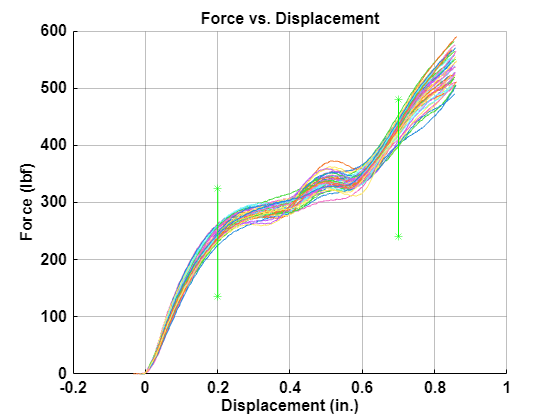

% Plot force vs. displacement
figure
hold on
for i = 1:length(data)
    plot(data(i).disp - data(i).fz, data(i).force)
end
title('Force vs. Displacement', 'FontSize', 14, 'FontWeight', 'bold', 'Color', 'k') % Set title properties
plot([0.2 0.2], [val0p2LSL val0p2USL],'g-*')
plot([0.7 0.7], [val0p7LSL val0p7USL],'g-*')
hold off
xlabel('Displacement (in.)', 'FontSize', 12, 'FontWeight', 'bold', 'Color', 'k') % Set x-axis label properties
ylabel('Force (lbf)', 'FontSize', 12, 'FontWeight', 'bold', 'Color', 'k') % Set y-axis label properties
grid on
legend({data.datasetname},'interpreter','none')
legend off

% Set plot background and text color
set(gcf, 'Color', 'w'); % Set background color to white
set(gca, 'Color', 'w'); % Set axes background color to white
set(gca, 'XColor', 'k', 'YColor', 'k'); % Set axes tick color to black
set(gca, 'FontSize', 10, 'FontWeight', 'bold'); % Set axes font properties
set(findall(gcf,'-property','FontSize'),'FontSize',12); % Set other text font size

%Print force vs. disp to PDF
currentDate = datetime('now', 'Format','uuuu-MM-dd'); %Get the current date
currentDateStr = char(currentDate); %Convert date to string
forceFilename = ['Force_vs_Displacement_', currentDateStr, '.pdf']; %Define file name/structure
print(forceFilename, '-dpdf', '-r300'); %Create PDF with 300 dpi resolution

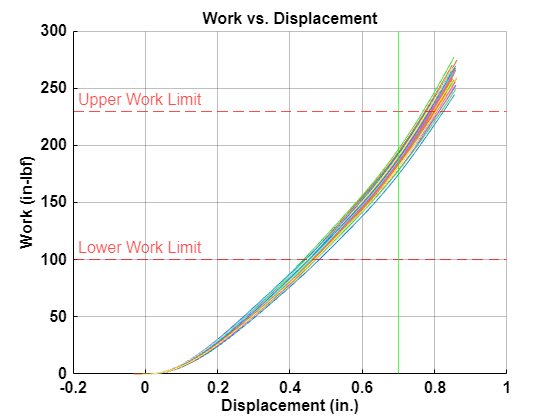

% Plot work vs displacement
figure
hold on
for i = 1:length(data)
    disp_adj = data(i).disp - data(i).fz;
    force_adj = data(i).force;
    work = cumtrapz(disp_adj, force_adj); % Cumulative work done at each displacement
    plot(disp_adj, work)
end
title('Work vs. Displacement', 'FontSize', 14, 'FontWeight', 'bold', 'Color', 'k') % Set title properties
yline(work_Ul, 'r--', 'Upper Work Limit', 'LabelHorizontalAlignment','left');
yline(work_Ll, 'r--', 'Lower Work Limit', 'LabelHorizontalAlignment','left');
xline(0.7, 'g-');
hold off
xlabel('Displacement (in.)', 'FontSize', 12, 'FontWeight', 'bold', 'Color', 'k') % Set x-axis label properties
ylabel('Work (in-lbf)', 'FontSize', 12, 'FontWeight', 'bold', 'Color', 'k') % Set y-axis label properties
grid on
legend({data.datasetname}, 'interpreter', 'none')
legend off

% Set plot background and text color
set(gcf, 'Color', 'w'); % Set background color to white
set(gca, 'Color', 'w'); % Set axes background color to white
set(gca, 'XColor', 'k', 'YColor', 'k'); % Set axes tick color to black
set(gca, 'FontSize', 10, 'FontWeight', 'bold'); % Set axes font properties
set(findall(gcf,'-property','FontSize'),'FontSize',12); % Set other text font size

%Print work vs. displacement to PDF
workFilename = ['Work_vs_Displacement_', currentDateStr, '.pdf']; %Define file name/structure
print(workFilename, '-dpdf', '-r300'); %Create PDF with 300 dpi resolution

function pathlist = generatePathList(mainsearchpath, filesearchstrings)
    numFiles = 0;
    for i = 1:numel(filesearchstrings)
        numFiles = numFiles + numel(dir(fullfile(mainsearchpath, filesearchstrings{i})));
    end

    pathlist = cell(numFiles, 1);
    idx = 1;
    for i = 1:numel(filesearchstrings)
        files = dir(fullfile(mainsearchpath, filesearchstrings{i}));
        for j = 1:numel(files)
            pathlist{idx} = fullfile(mainsearchpath, files(j).name);
            idx = idx + 1;
        end
    end
end

function [data] = getCSVdata(pathlist, skiplines, columnnames, columnindexes)
    % Opens test files and reads columns of data to an output structure
    numFiles = length(pathlist);
    maxRows = 800; % Adjust this value based on the expected size of your data
    %Note: common file length is ~330 lines

    data(numFiles).datasetname = '';
    for k = 1:length(columnnames)
        data(numFiles).(columnnames{k}) = NaN(maxRows, 1);
    end

    for j = 1:numFiles
        try
            % Check if the file exists
            if exist(pathlist{j}, 'file') ~= 2
                error('File not found: %s', pathlist{j});
            end
            
            delimitedpath = textscan(pathlist{j}, '%s', 'delimiter', '\');
            datasetname = delimitedpath{1}{end};
            data(j).datasetname = datasetname;

            fid = fopen(pathlist{j});
            if fid == -1
                error('Failed to open file: %s', pathlist{j});
            end
            
            % Skip lines
            for i = 1:skiplines
                fgetl(fid);
            end

            i = 1;
            while ~feof(fid)
                line = fgetl(fid);
                if ~isempty(line)
                    parsedline = textscan(line, '%f', 'delimiter', ',');
                    parsedline = parsedline{1};

                    if i > maxRows
                        maxRows = maxRows * 2;
                        for k = 1:length(columnnames)
                            data(j).(columnnames{k})(maxRows, 1) = NaN;
                        end
                    end

                    for k = 1:length(columnnames)
                        try
                            data(j).(columnnames{k})(i, 1) = parsedline(columnindexes(k));
                        catch
                            fprintf(['\nbad file: ' data(j).datasetname '\n']);
                            fclose(fid);
                            break;
                        end
                    end
                    i = i + 1;
                end
            end

            for k = 1:length(columnnames)
                data(j).(columnnames{k}) = data(j).(columnnames{k})(1:i-1);
            end
            fclose(fid);
        catch err
            % Handle any errors that occur during file reading
            warning('Error reading file: %s\n%s', pathlist{j}, err.message);
            % You can choose to continue processing other files or abort here
        end
    end
end


function result = determinePassFail(value, lowerLimit, upperLimit)
    if value > upperLimit
        result = 'High';
    elseif value < lowerLimit
        result = 'Low';
    else
        result = 'Pass';
    end
end

function [] = writestructure2(structure, ifields)
    [file, path] = uiputfile('*.csv', 'Save CSV Output');

    if file == 0
        warning('User Canceled File Write');
        return;
    end

    fullFileName = fullfile(path, file);
    fields = fieldnames(structure);

    % Open file for writing
    fid = fopen(fullFileName, 'w');
    if fid == -1
        error('Cannot open file for writing: %s', fullFileName);
    end

   % Create header
    maxHeaderLength = 800; % Maximum length of the header string
    numFields = length(ifields); % Number of fields to process
    header = char(zeros(1, maxHeaderLength)); % Preallocate header as a char array
    headerCell = cell(1, numFields); % Preallocate headerCell as a cell array

    headerIndex = 1; % Initialize index for header
    cellIndex = 1; % Initialize index for headerCell

    for i = 1:numFields
        fieldName = fields{ifields(i)};
        len = length(fieldName);
        if headerIndex + len <= maxHeaderLength
            header(headerIndex:headerIndex+len-1) = fieldName;
            headerIndex = headerIndex + len;
            header(headerIndex) = ','; % Add comma
            headerIndex = headerIndex + 1;
            headerCell{cellIndex} = fieldName;
            cellIndex = cellIndex + 1;
        else
            break;
        end
    end

    % Remove unused portion of the preallocated arrays
    header = header(1:headerIndex-1);
    headerCell = headerCell(1:cellIndex-1);

    % Write header to file
    fprintf(fid, '%s\n', header);

    % Write data
    numRows = length(structure);
    numFields = length(headerCell);

    for i = 1:numRows
        row = '';
        for j = 1:numFields
            fieldName = headerCell{j};
            value = structure(i).(fieldName);

            if isnumeric(value)
                valueStr = num2str(value);
            elseif ischar(value)
                valueStr = value;
            elseif iscell(value)
                valueStr = value{1}; % Assuming single cell element
            else
                valueStr = 'NaN';
            end

            row = [row, valueStr, ','];
        end

        % Remove the last comma and write row to file
        row = row(1:end-1);
        fprintf(fid, '%s\n', row);
    end

    fclose(fid);
end
           